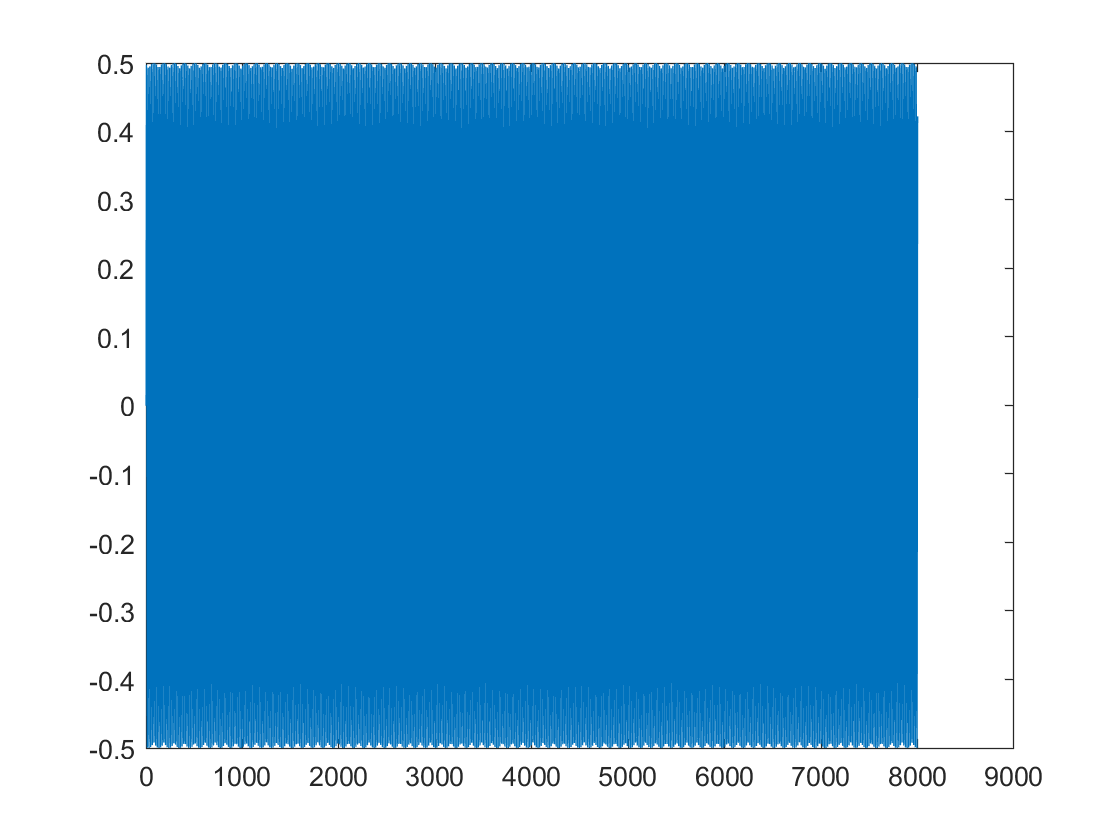

%ECOMMS Lab Project 1 Example 
%S. Mandayam, Rowan University 
%This program generates a 1-second duration  
%Asharp signal (466.16 Hz) with a specified SNR

%Specify SNR 
snr=10; 

%Generate Asharp signal
t=[0:1/8e3:1.0]';
s = 0.5*sin(2*pi*466.16*t);  
sound(s); 

%Compute signal variance 
var_s = cov(s); 

%Calculate required noise variance 
var_noise=var_s/(10^(snr/10)); 

%Generate noise 
n=sqrt(var_noise)*randn(length(s),1); sound(n);

%Add signal to noise and generate message 
m=s+n; sound(m); 

plot(s);

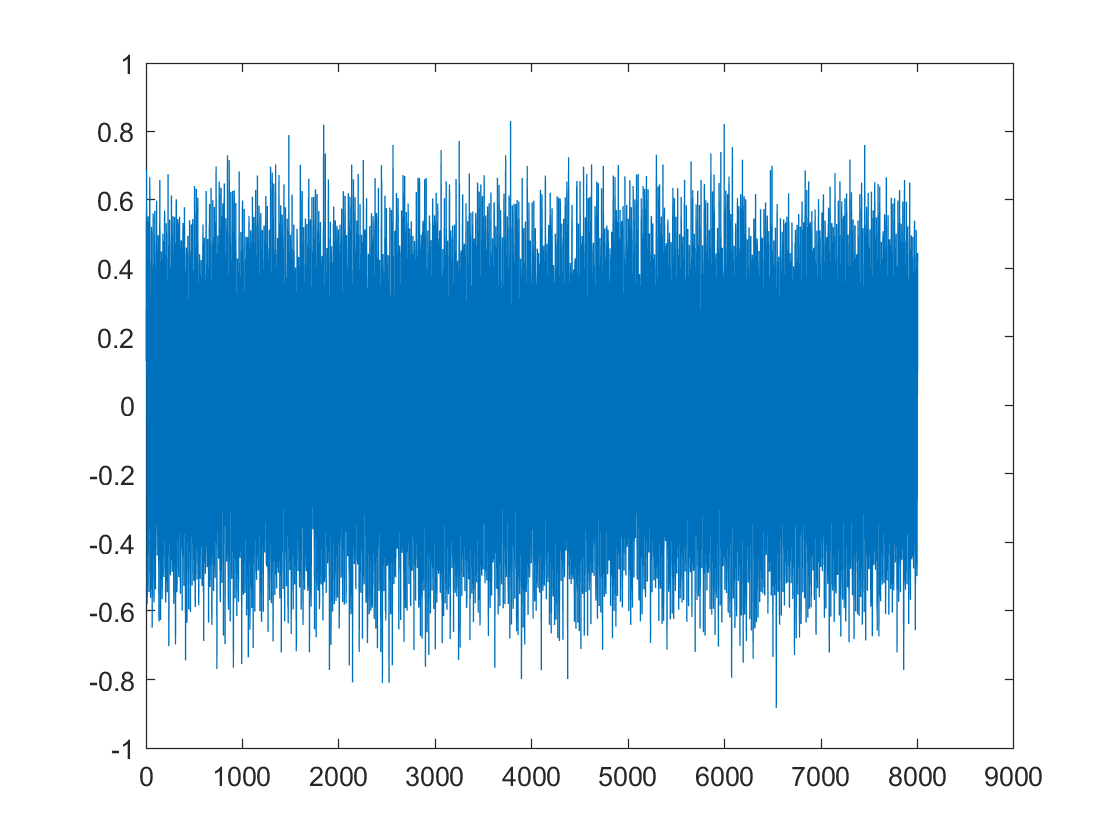

plot(m);